clear all;
close all
clc; clf;

Opgave 1: De functie definieren

function [napprox, approx] = bisec(f, aa, bb ,delta)
    a = aa; b = bb;
    fa = f(a); fb = f(b);
    K = ceil(-log2(delta/(b-a)));
    approx = nan(1, K); napprox = 0;
    if fa*fb >=0
        napprox = 1;
        return
    end
    for i = 1:K
        m = (a + b)/2;
        approx(i) = m;
        napprox = napprox + 1;
        fm = f(m);
        if fm == 0
            return
        end
        if fm*fa < 0
            b = m; fb = fm;
        else
            a = m; fa = fm;
        end
    end
end

nu effectief invullen

f1 = @(x) sin(x);
[n1, x_star1] = bisec(f1, -0.5, 1, 10^(-10));
x_star1(n1)

ans = -2.9104e-11


f2 = @(x) sin(x);
[n2, x_star2] = bisec(f2, -1, 1, 10^(-10));
x_star2(n2)

ans = 0


f3 = @(x) (x-1)^2;
[n3, x_star3] = bisec(f3, -1, 2, 10^(-10));
x_star3(n3)

ans = NaN

plotten

figure(1);clf;
for i = 1:100
    delta = 10^(-i);
    [n, x_star_] = bisec(f1, -0.5, 1, delta);
    x_star = x_star_(n);
    y(i) = abs(0 - x_star); 
    x(i) = n;
end
semilogy(x,y,'-');

ander algoritme

function [i, root] = newton_raphson(f, df, x0, tol, max_iter)

    x = x0;
    for i = 1:max_iter
        fx = f(x);
        dfx = df(x);
        if dfx == 0
            error('Derivative is zero. Stopping to avoid division by zero.');
        end
        x_new = x - fx / dfx;
        if abs(x_new - x) < tol
            root = x_new;
            return;
        end
        x = x_new;
    end
    root = x;
end

clear all;
close all
clc; clf;

f = @(x) sin(x);
df = @(x) cos(x);
[n, x_star] = newton_raphson(f, df, -1, 10^(-10), 10^10);
x_star

x_star = 0

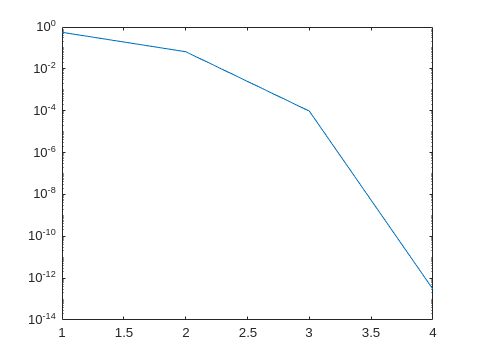


figure(1);clf;
for i = 1:100
    [n, x_star] = newton_raphson(f, df, -1, 10^(-10), i);
    y(i) = abs(0 - x_star); 
    x(i) = n;
end
semilogy(x,y,'-');

Opgave 2

function [root, iter] = newton_raphson_2d(f, J, x0, tol, max_iter)
    x = x0;
    for iter = 1:max_iter
        fx = f(x);
        Jx = J(x);
        
        if norm(fx) < tol
            root = x;
            return;
        end
        h = Jx \ fx;
        x = x - h;
        if norm(h) < tol
            break;
        end
    end
    root = x;
end



f = @(x) [
    x(1)*(3 - x(1) - 2*x(2));
    x(2)*(2 - x(1) - x(2))
];

J = @(x) [
    3 - 2*x(1) - 2*x(2), -2*x(1);
    -x(2), 2 - x(1) - 2*x(2)
];

x0 = [4; 1];

[root, iter] = newton_raphson_2d(f, J, x0, 1e-5, 50)

root =     3.0000
   -0.0000


iter = 6